digital signal processing final project :

1.‫Feature Extraction 

use MFCC.m 

2.Feature Matching 

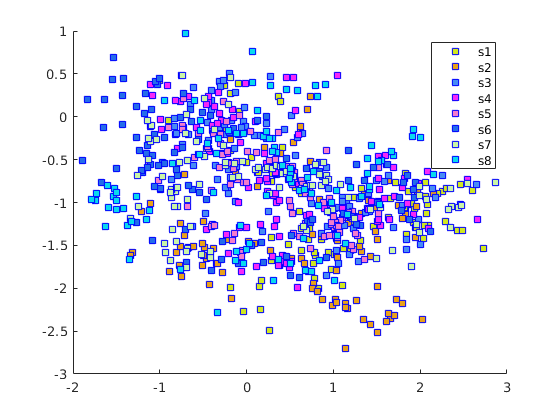

address='./train/';
type='.wav';
figure;
for i=1:8 
    [sound,fs]=audioread(strcat(address,'s',int2str(i),type));
    mfcc=MFCC(sound,fs,256,100);
    scatter(mfcc(5,:),mfcc(6,:),'s','filled','MarkerEdgeColor','b','MarkerFaceColor',[rand() rand() rand()],'DisplayName',strcat('s',int2str(i)));
    legend
    hold on
end
hold off

it is obvious that mfcc of diffrent sounds have overlap if we use only 2 diminsion of mfcc vector, therefore if we take advantage of other diminsions of mfcc vector , data overlap reduces.

KNN:

first we create train matrix:

train_mat=zeros(12,800);
address='./train/';
type='.wav';
for i=1:8 
    [sound,fs]=audioread(strcat(address,'s',int2str(i),type));
    mfcc=MFCC(sound,fs,256,100);
    train_mat(:,(i-1)*100+1:i*100)=mfcc;
end

then we will predict each test signals using knn_classifier

knn_predict=zeros(8,1);
address='./test/';
type='.wav';
for i=1:8 
    [sound,fs]=audioread(strcat(address,'s',int2str(i),type));
    mfcc=MFCC(sound,fs,256,100);
    knn_predict(i,1)=knn_classifier(mfcc,train_mat,20);
end
knn_predict

knn_predict =      1
     2
     3
     4
     5
     6
     7
     2


knn_classifier is developed by two different methods which can be selected in matfile. if we use knn_search with k equal to 20 , prediction is approximatly true , however this prediction is not valid.

ANN:

first we creat train and target matrices

train_mat=zeros(12,800);
target_mat=zeros(8,800);
address='./train/';
type='.wav';
for i=1:8 
    [sound,fs]=audioread(strcat(address,'s',int2str(i),type));
    mfcc=MFCC(sound,fs,256,100);
    train_mat(:,(i-1)*100+1:i*100)=mfcc;
    temp=zeros(8,100);
    for j=1:100
        temp(i,j)=1;
    end
    target_mat(:,(i-1)*100+1:i*100)=temp;
end

then we creat a one layer nework and train it with our data set

net=feedforwardnet(100);
net=configure(net,train_mat,target_mat);
net=train(net,train_mat,target_mat);
view(net);

now lets check our prediction:

address='./test/';
type='.wav';
final_prediction=zeros(8,1);
for i=1:8 
    [sound,fs]=audioread(strcat(address,'s',int2str(i),type));
    mfcc=MFCC(sound,fs,256,100);
    temp=zeros(100,1);
    for j=1:100
        out=net(mfcc(:,j));
        [value,index]=max(out);
        temp(j,1)=index;
    end
    final_prediction(i,1)=mode(temp);
end
final_prediction

final_prediction =      1
     2
     3
     4
     5
     6
     7
     8


if we set hidden layer size above 100 the neural network predics test data set accurately.